# Part 3: Anomaly Detection with Statistical Approaches and Machine Learning

# 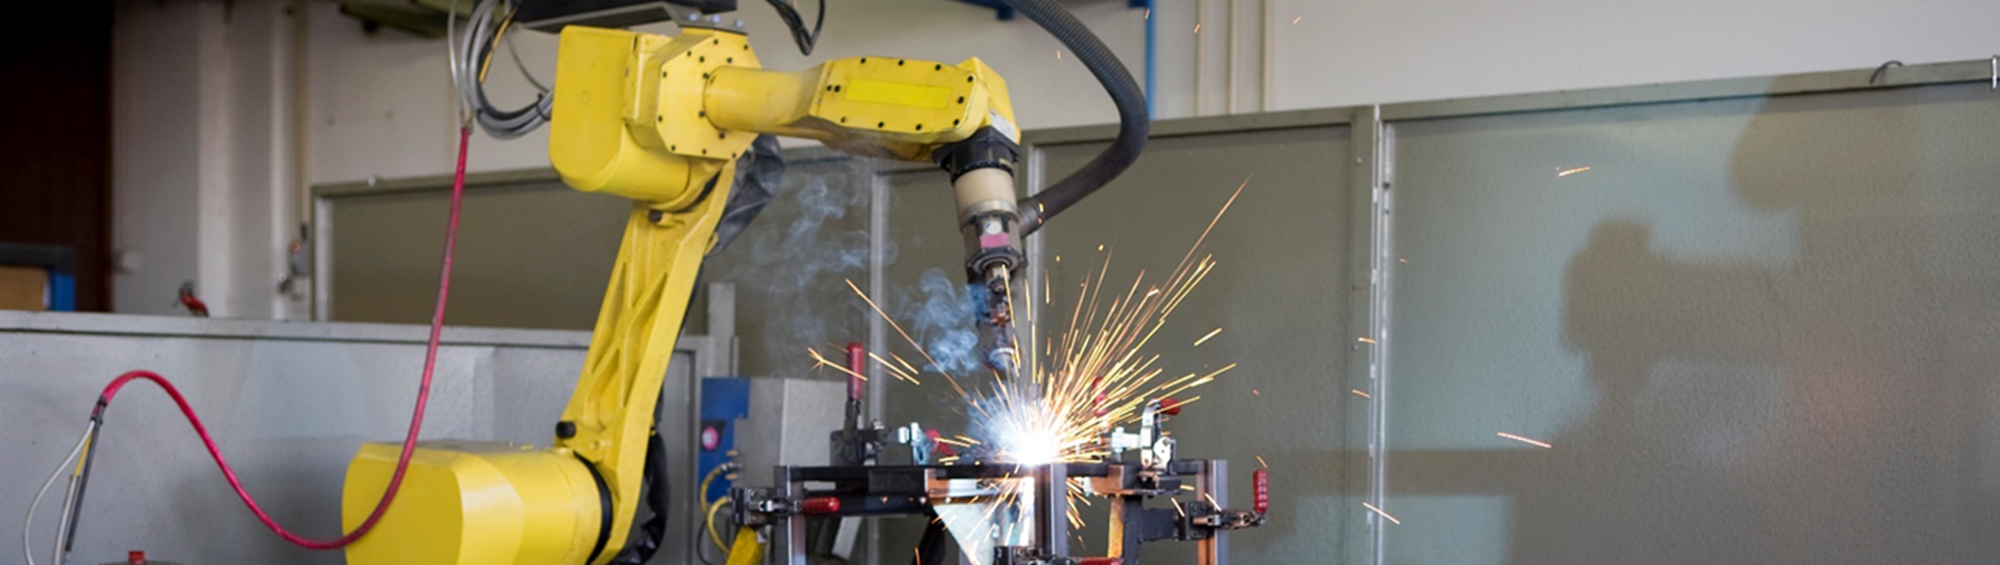

This example illustrates various statistical and machine learning approaches to anomaly detection. We use the same operating data collected from vibration sensors before and directly after a scheduled maintenance period. Since the focus of this example is on modeling approaches, we use the same features that were computed from raw data using the [Diagnostic Feature Designer App](https://www.mathworks.com/help/predmaint/gs/explore-features-in-diagnostic-feature-designer.html) in the previous sections.

## **Prepare Data for Machine Learning**

In the first section, we extracted 12 highly ranked features from a small subset of the larger dataset of 17,642 signals. While large data sets are needed for deep learning, machine learning approaches require much less data. To illustrate that, we'll work with a "small" subset of ~4% of the full set.

Like in the second section, we use the data before maintenance as a stand-in for anomalies. After maintenance the machine is healthy and produces "normal"  data.  Typically you have much less "anomalous" data at your disposal, but good news is that most anomaly detection approaches assume exactly that: that you primarily have normal data.

load("FeatureSmall.mat");
rng;

% show distribution in this small data set
st = groupcounts(featureSmall,"label")

st = 2×3 table
     label     GroupCount    Percent
    _______    __________    _______

    Anomaly        74        11.385 
    Normal        576        88.615 


outlierFraction = st.Percent(1)/100;    % remember fraction of anomalies in data

% divide subset into train and (held out) test
idxSmall = cvpartition(featureSmall.label,'holdout',0.2);
featSmallTrain = featureSmall(idxSmall.training,:);
featSmallTest = featureSmall(idxSmall.test,:);
trueAnomaliesTest = featSmallTest.label;

## Supervised Approach: Train Classifiers

The original dataset is fairly balanced, in the same order samples of "after" and "before" maintenance, representing normal and anomalous operating conditions. For use cases where you have lots of labeled data in both conditions, you can simply apply standard supervised learning and build classifiers. The chart below illustrates the relationship between amount of labeled data available and some possible approaches to anomaly detection.

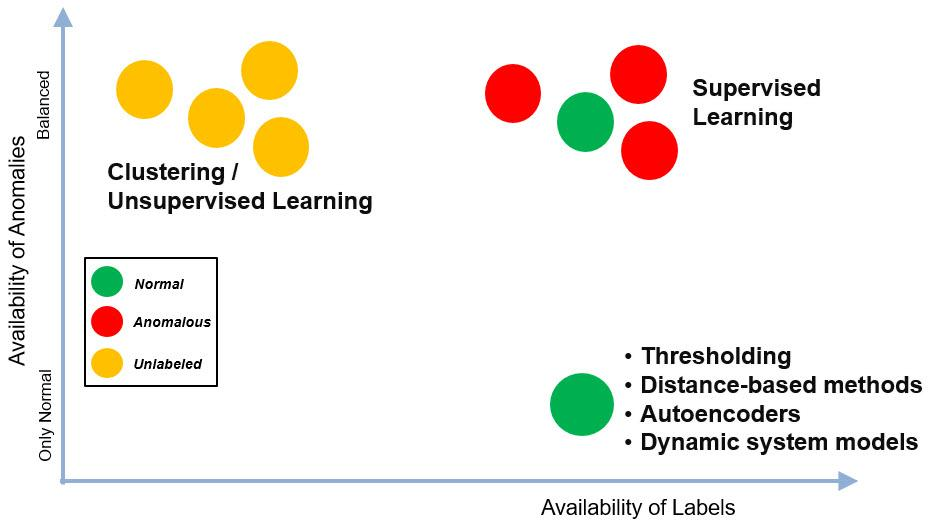

For this data set, we are in the upper right quadrant where supervised learning is appropriate. Several machine learning algorithms achieve good classification accuracy - indicating that the features we extracted earlier are pretty good. Below we show validation accuracy, and the confusion matrix for the best model, the tree ensemble.

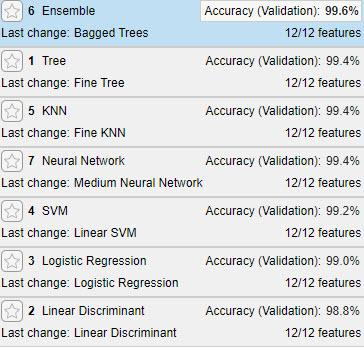

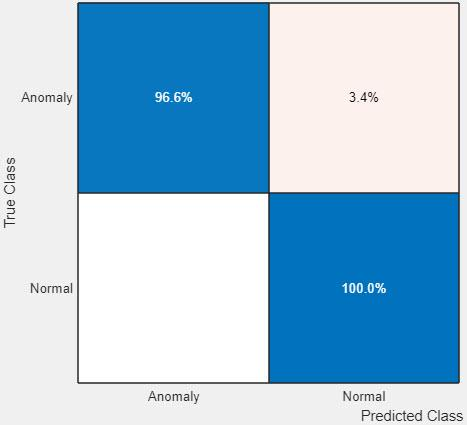

For the rest of this example, to be realistic, we will pretend that we have primarily normal data available by removing the "Before" data from the training set. We can then demonstrate how to apply the methods mentioned in the lower right quadrant: train on normal data only, then try to identify anomalies.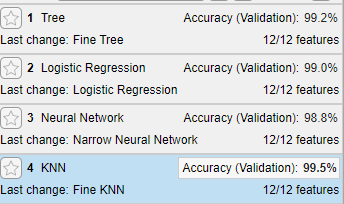

## Statistical & Machine Learning Approaches to Anomaly Detection

### Detect Anomalies with One-class SVM

Support Vector Machines are powerful classifiers, and their variant training only one-class models the "normal" data and works well for identifying anomalies.

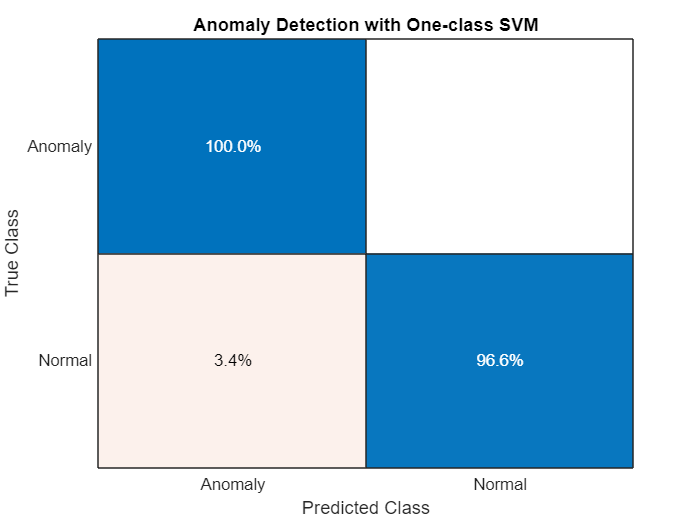

% identify subset of "normal" (healthy) data in training 
healthyIdx = featSmallTrain.label=="Normal";
trainHealthy = featSmallTrain(healthyIdx,2:13);   % can safely skip labels column since we only have one class
trainHealthyN = size(trainHealthy,1);

% train one-class SVM. On this data, training just on the "normal" (healthy) data works better
mdlSVM = fitcsvm(trainHealthy,ones(trainHealthyN,1),'Standardize',true,'OutlierFraction',0);

% this variant trains on all data (including anomalies), with the estimated fraction
%mdlSVM = fitcsvm(featSmallTrain(:,2:13),ones(size(featSmallTrain,1),1),'Standardize',true,'OutlierFraction',outlierFraction);

% apply to "small" test data (which has both anomalies and healthy data)
[~,scoreSVM] = predict(mdlSVM,featSmallTest(:,2:13));
isanomalySVM = scoreSVM<0;
predSVM = categorical(isanomalySVM, [1, 0], ["Anomaly", "Normal"]);

confusionchart(trueAnomaliesTest,predSVM,Title="Anomaly Detection with One-class SVM",Normalization="row-normalized");

We can see the one-class SVM performs well, all anomalous samples are identified, and only 4% of the "healthy" ones are miscassified.

### Detect Anomalies with Isolation Forest

The decision trees of an isolation forest isolate each observation in a leaf. How many decisions a sample passes through to get to its leaf is a measure of how complicated it was to isolate it from the others. The average depth of trees for a specific sample is used as their anomaly score, and returned by [iforest](https://mathworks.com/help/stats/iforest.html).

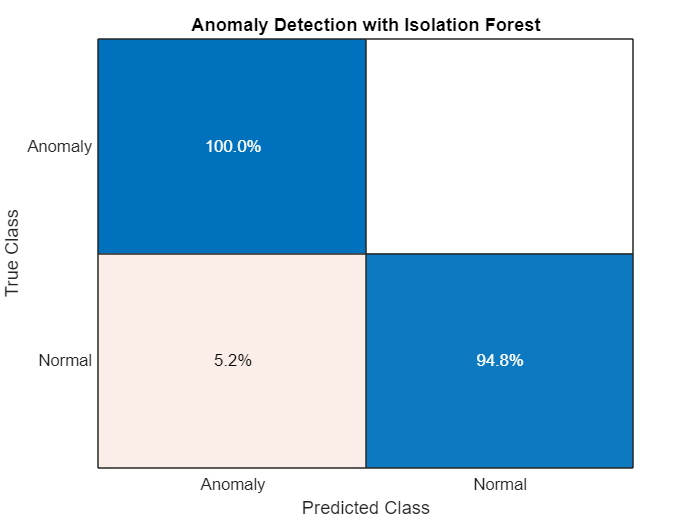

% train on normal (healthy) data only. Need to tune the ContimationFraction!
[mdlIF,~,scoreTrainIF] = iforest(trainHealthy,'ContaminationFraction',0.05);

[isanomalyIF,scoreTestIF] = isanomaly(mdlIF,featSmallTest(:,2:13));
predIF = categorical(isanomalyIF, [1, 0], ["Anomaly", "Normal"]);

confusionchart(trueAnomaliesTest,predIF,Title="Anomaly Detection with Isolation Forest",Normalization="row-normalized");

On this data, the isolation forest doesn't do as well as the one-class SVM, but it has become popular for outperforming other methods on other data sets.

To better understand how the isolation forest works, it can be helpful to visualize the distribution of its anomaly scores.

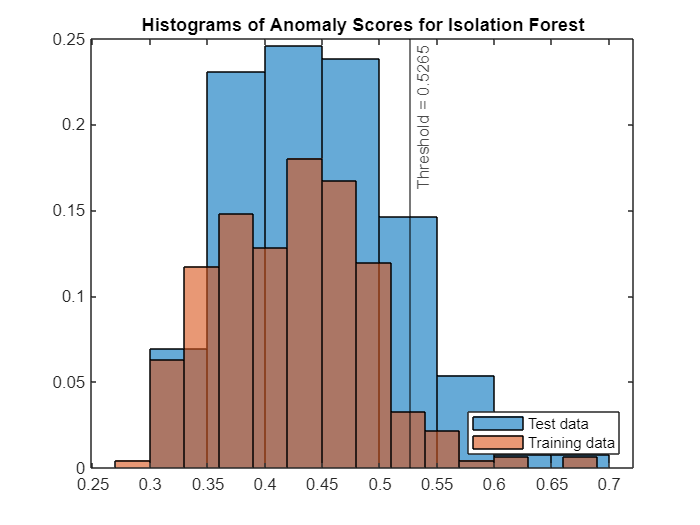

% visualize the anomaly score distributions for train vs test 
figure;
histogram(scoreTestIF,Normalization="probability");
hold on
histogram(scoreTrainIF,Normalization="probability");
xline(mdlIF.ScoreThreshold,"k-", join(["Threshold =" mdlIF.ScoreThreshold]))
legend("Test data","Training data",Location="southeast")
title("Histograms of Anomaly Scores for Isolation Forest")
hold off

The difference in the distribution of training and test data is the latter contains some "anomalous" data -while the training didn't, and we set the threshold just right to correctly identify the bulk of that anomalous data.  

### Detect Anomalies with Robust Covariance

As statistical approach for detecting  anomalies, you can estimate robust covariances (and means), and then identify anomalies as being on the fringes of the distribution (outliers!). Robust estimators handle data that contains outliers and deviate from the assumption of multivariate normality. [robustcov](https://www.mathworks.com/help/stats/robustcov.html) can accomplish that.

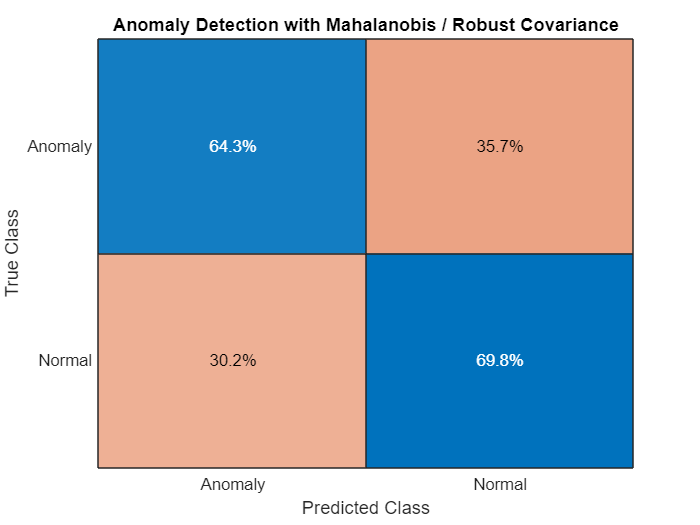

featSmallTrainM = table2array(featSmallTrain(:,2:13));    % robustcov expects input as matrix, not table
featSmallTestM = table2array(featSmallTest(:,2:13)); 

% compute robust covariance on both normal and (typically only a little)
% anomalous data - which is not the case for this data!
[sigma,mu,mahalDistRobust,~] = robustcov(featSmallTrainM, OutlierFraction=outlierFraction);
sigRobustThresh = sqrt(chi2inv(1-outlierFraction,size(featSmallTrainM,2)));

% identify anomalies on new (test) data with Mahalanobis distance
scoreTestMahal = pdist2(featSmallTestM,mu,"mahalanobis",sigma);
isanomalyMahal = scoreTestMahal > sigRobustThresh;
predMahal = categorical(isanomalyMahal, [1, 0], ["Anomaly", "Normal"]);

confusionchart(trueAnomaliesTest,predMahal,Title="Anomaly Detection with Mahalanobis / Robust Covariance",Normalization="row-normalized");

Robust covariance is not working well on this data, but since we had good results with the other two methods, we can move on; and now you have a template how to apply this method to your data. Maybe you'll get better results!

### Visualize various Anomaly Detection Methods

Visualizations can help explain why classification methods work and when they are not, and that applies also to anomaly detection. If you are working with many dimensions, it's essential to reduce the dimensionality before visualizing. One handy method to compress multiple dimensions is Stochastic Neighborhood Embedding [tsne](https://www.mathworks.com/help/stats/tsne.html). t-SNE has a tendency to group the data in clusters because it minimizes the Kullback-Leibler divergence in the two-dimensional space, but don't overinterpret them: those groupings don't always exist in the original high-dimensional data.

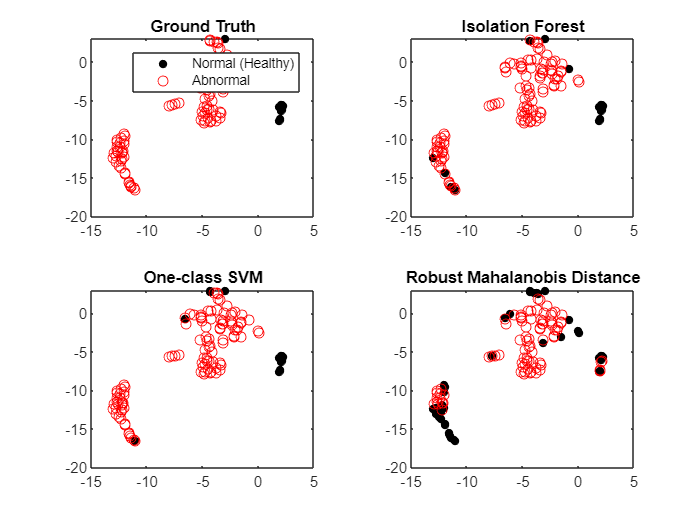

% use t-SNE to reduce the 12 features into a two-dimensional space
T = tsne(featSmallTestM);

% compare the various anomaly detection methods visually, starting with
% "ground truth" (labels)
figure;
tiledlayout(2,2)
nexttile
gscatter(T(:,1),T(:,2),trueAnomaliesTest,"kr",".o",[],"off");
title("Ground Truth")
legend("Normal","Anomalous");
nexttile(2)
gscatter(T(:,1),T(:,2),predIF,"kr",".o",[],"off")
title("Isolation Forest")
nexttile(3)
gscatter(T(:,1),T(:,2),predSVM,"kr",".o",[],"off")
title("One-class SVM")
nexttile(4)
gscatter(T(:,1),T(:,2),predMahal,"kr",".o",[],"off")
title("Robust Mahalanobis Distance")

We can see that the cluster of anomalous data in the upper area, and the cluster of normal data in the lower left, are mostly correctly identified by the One-class SVM and isolation forest, while they aren't separated by the Mahalanobis-distance (at least in the two-dimensional space that tsne transformed the 12 features). 

### Apply Clustering to Detect Anomalies

You can also apply clustering to identify groups in your data, and relate which of those groups align with normal versus anomalous samples. That's much easier done visually, so let's use the two dimensions which t-SNE summarized the original 12 features, and apply a distance-based clustering method like [dbscan](https://www.mathworks.com/help/stats/dbscan.html). It requires some experimentation to find the right settings for the distance parameter epsilon and minimum cluster size.

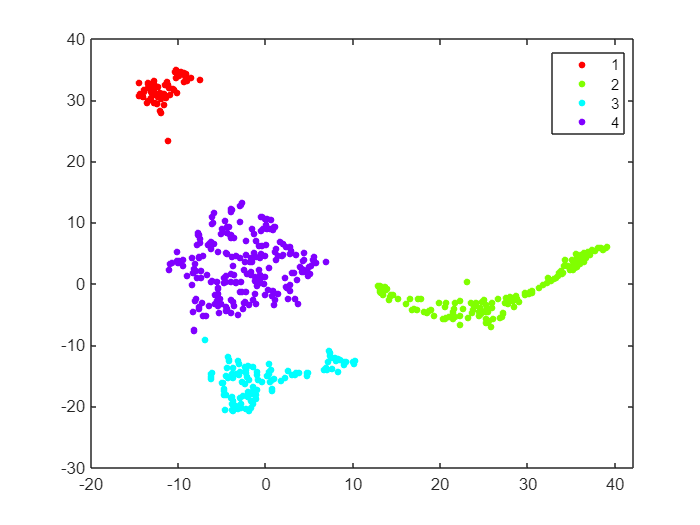

trainSmallSNE = tsne(featSmallTrainM);
mdlDB = dbscan(trainSmallSNE,5,20);
figure
gscatter(trainSmallSNE(:,1),trainSmallSNE(:,2),mdlDB);

## **Summary**

To recap, as example for process data we used timeseries signals from a three-axis accelerometer taken from an industrial machine before and after maintenance, the same data as in the previous section. To simulate use cases more typical for machine learning where you have limited labeled data, this example uses a small subset of ~4% of the original data.

Because we had a labeled dataset, we were able to train supervised machine learning models. If you can extract useful features, machine learning can often give you comparable or better results than deep learning on far less data.you comparable or better results than deep learning on far less data.

We then applied four approaches to anomaly detection that need little to no labeled anomalies:

- One-class SVM

- Isolation Forest (new in R2021b)

- Robust covariance and Mahalanobis distance

- DBSCAN clustering

On this data, performance for the one-class SVM was best, isolation forest was acceptable, and Mahalanobis distance did not work well. 

*Copyright 2021 The MathWorks, Inc.*